## First Test with Good Wheel

clear;clc;clf
[y_true,Fs] = audioread("data/Trial 1/True wheel.m4a");

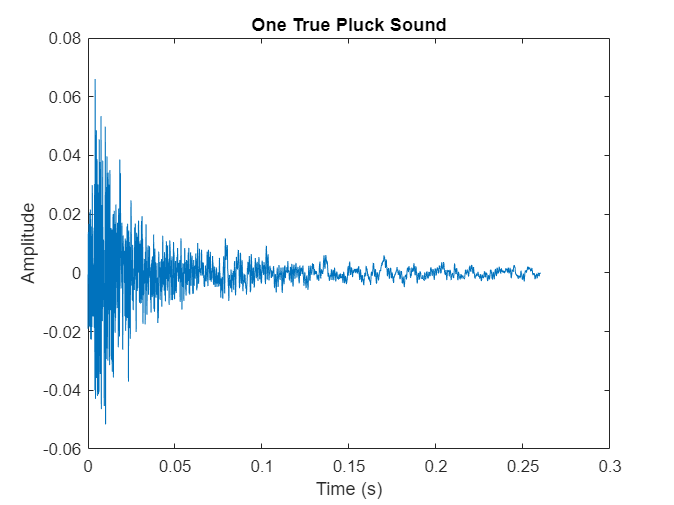

true_pluck = y_true(1.24*Fs:1.5*Fs);
t_true = linspace(0,length(true_pluck)/Fs,length(true_pluck));
plot(t_true, true_pluck)
title("One True Pluck Sound");
ylabel("Amplitude");
xlabel("Time (s)");

sound(true_pluck, Fs)

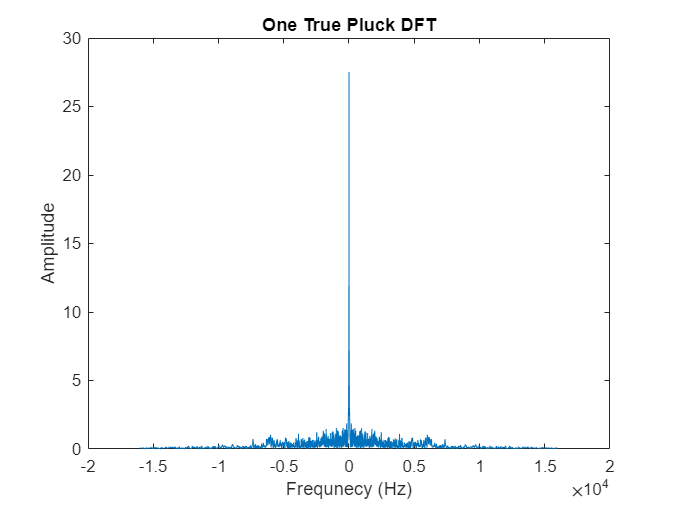

true_N = length(true_pluck);
true_f = linspace(-Fs/2, Fs/2 - Fs/true_N, true_N) + Fs/(2*true_N)*mod(true_N, 2);

true_pluckfft = fft(abs(true_pluck));

true_shiftpluckfft = fftshift(abs(true_pluckfft));

plot(true_f, true_shiftpluckfft)
title("One True Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")


true_f(true_shiftpluckfft == max(true_shiftpluckfft))

ans = 8.5709e-14

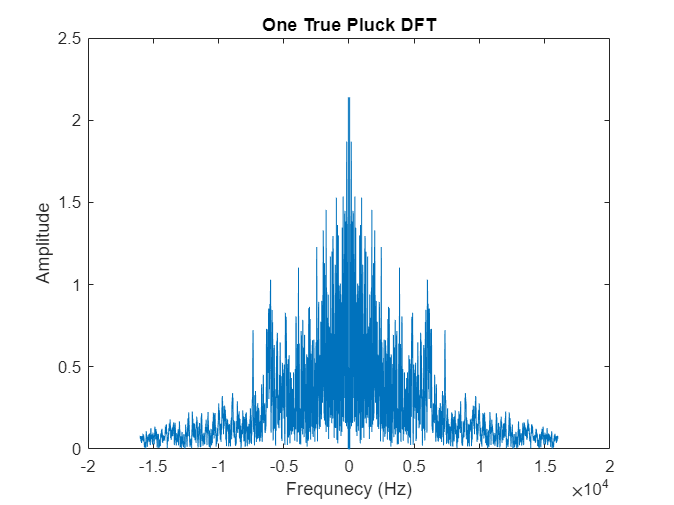



true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;
true_shiftpluckfft(true_shiftpluckfft == max(true_shiftpluckfft)) = 0;




plot(true_f, true_shiftpluckfft)
title("One True Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

## First Test with Bad Wheel

[y_bad,Fs] = audioread("data/Trial 1/Bad wheel .m4a");

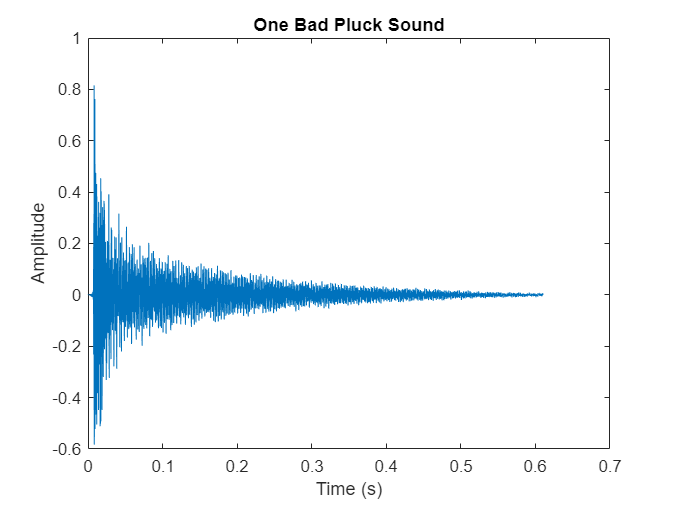

bad_pluck = y_bad(1.19*Fs:1.8*Fs);
t_bad = linspace(0,length(bad_pluck)/Fs,length(bad_pluck));
plot(t_bad, bad_pluck)
title("One Bad Pluck Sound");
ylabel("Amplitude");
xlabel("Time (s)");

sound(bad_pluck, Fs)

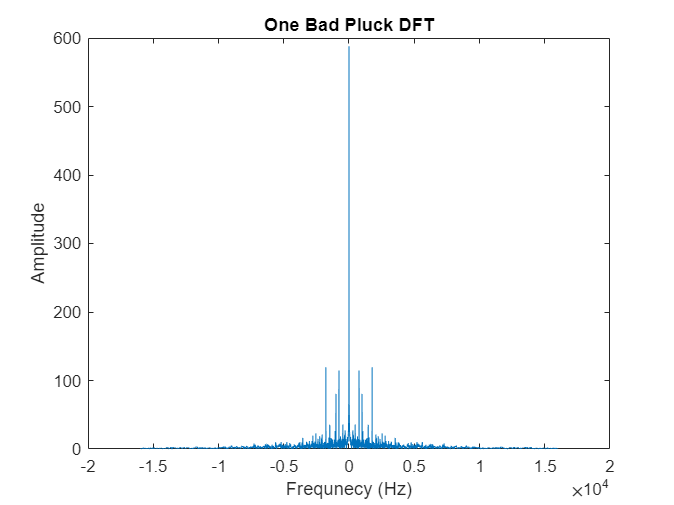

bad_N = length(bad_pluck);
bad_f = linspace(-Fs/2, Fs/2 - Fs/bad_N, bad_N) + Fs/(2*bad_N)*mod(bad_N, 2);

bad_pluckfft = fft(abs(bad_pluck));

bad_shiftpluckfft = fftshift(abs(bad_pluckfft));

plot(bad_f, bad_shiftpluckfft)
title("One Bad Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")


bad_f(bad_shiftpluckfft == max(bad_shiftpluckfft))

ans = 9.6290e-13

## Second Test with Better Wheel

[y_better,Fs] = audioread("better-1.flac");

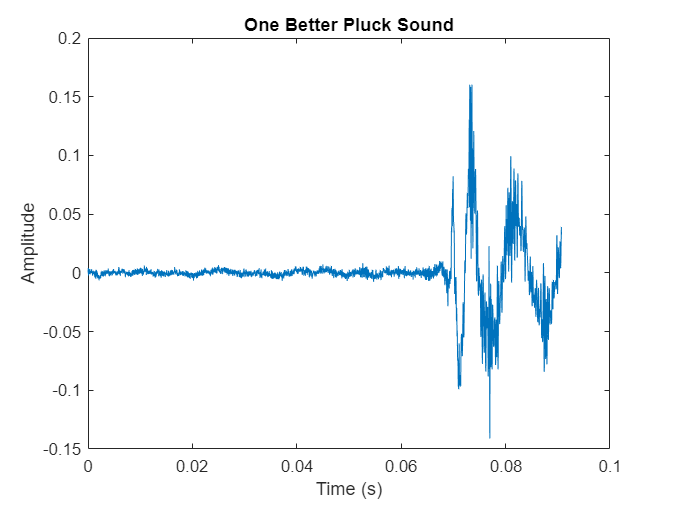

better_pluck = y_better(1:4000);
t_better = linspace(0,length(better_pluck)/Fs,length(better_pluck));
plot(t_better, better_pluck)
title("One Better Pluck Sound");
ylabel("Amplitude");
xlabel("Time (s)");

sound(better_pluck, Fs)

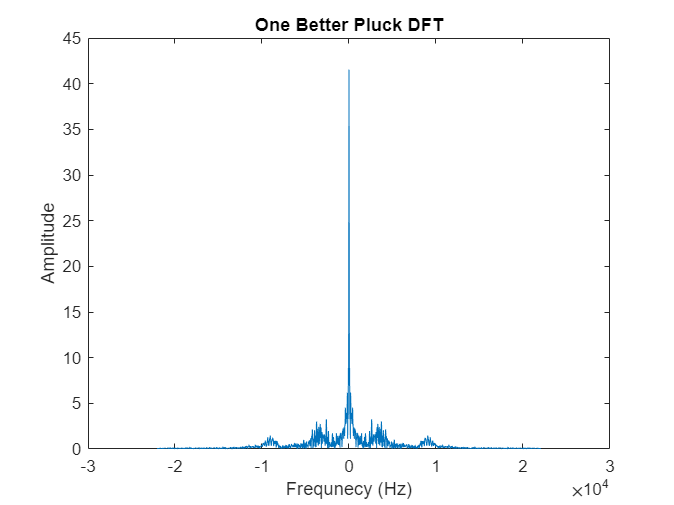

better_N = length(better_pluck);
better_f = linspace(-Fs/2, Fs/2 - Fs/better_N, better_N) + Fs/(2*better_N)*mod(better_N, 2);

better_pluckfft = fft(abs(better_pluck));

better__shiftpluckfft = fftshift(abs(better_pluckfft));

plot(better_f, better__shiftpluckfft)
title("One Better Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

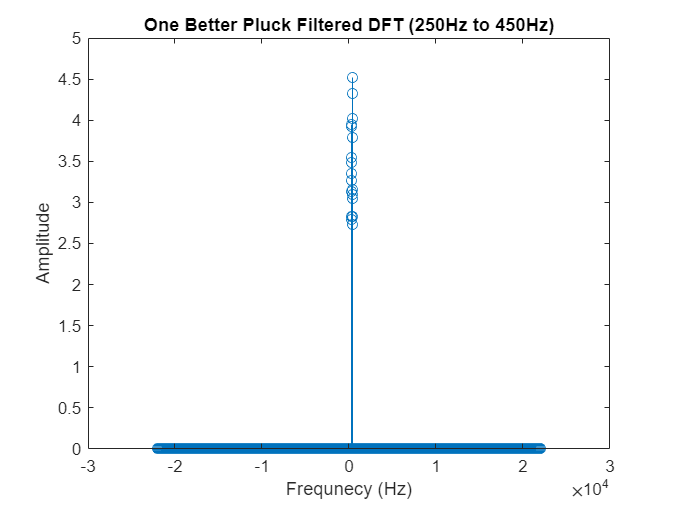


filter = zeros(length(better_f), 1);
filter(better_f >= 250 & better_f <= 450) = 1;

filtered = better__shiftpluckfft' .* filter;

stem(better_f, filtered)
title("One Better Pluck Filtered DFT (250Hz to 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

## Second Test with Bad Wheel

[y_bad,Fs] = audioread("data\Trial 2\bad-1.flac");

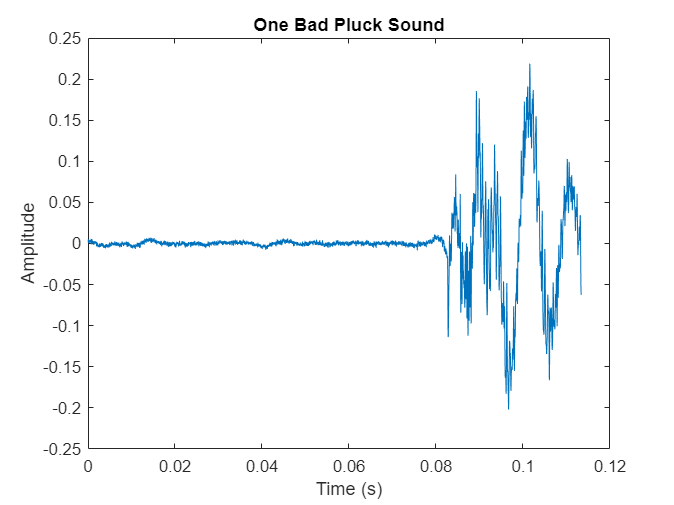

bad_pluck = y_bad(1000:6000);
t_bad = linspace(0,length(bad_pluck)/Fs,length(bad_pluck));
plot(t_bad, bad_pluck)
title("One Bad Pluck Sound");
ylabel("Amplitude");
xlabel("Time (s)");

sound(bad_pluck, Fs)

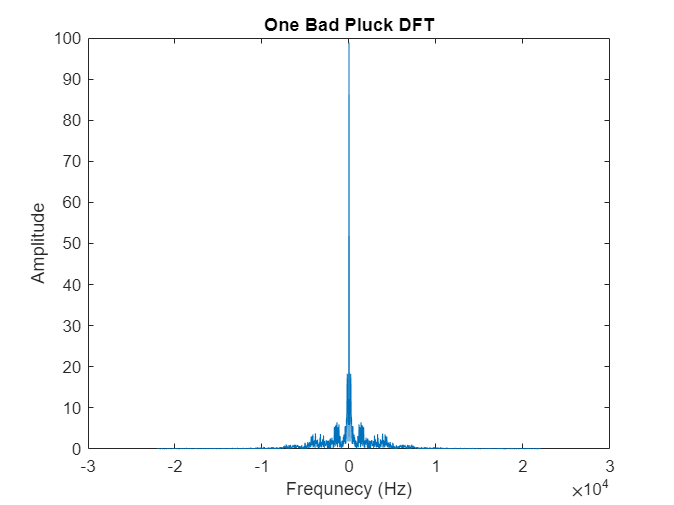

bad_N = length(bad_pluck);
bad_f = linspace(-Fs/2, Fs/2 - Fs/bad_N, bad_N) + Fs/(2*bad_N)*mod(bad_N, 2);

bad_pluckfft = fft(abs(bad_pluck));

bad_shiftpluckfft = fftshift(abs(bad_pluckfft));

plot(bad_f, bad_shiftpluckfft)
title("One Bad Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

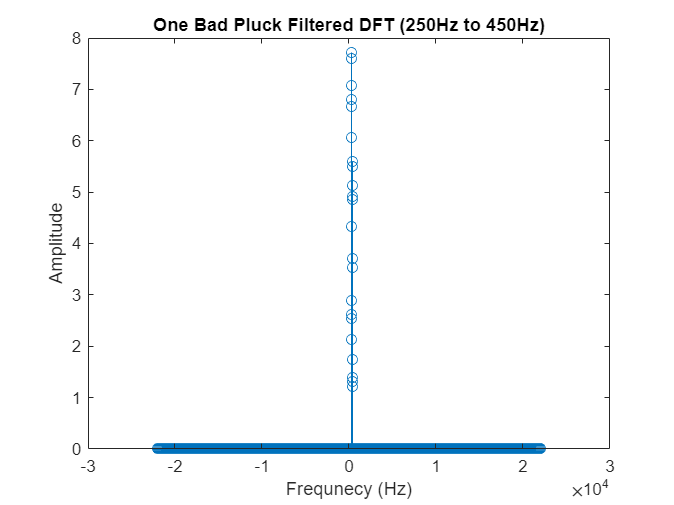


filter = zeros(length(bad_f), 1);
filter(bad_f >= 250 & bad_f <= 450) = 1;

filtered = bad_shiftpluckfft' .* filter;

stem(bad_f, filtered)
title("One Bad Pluck Filtered DFT (250Hz to 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

## Second Test with Worst Wheel

[y_worst,Fs] = audioread("data/Trial 2/worst-1.flac");

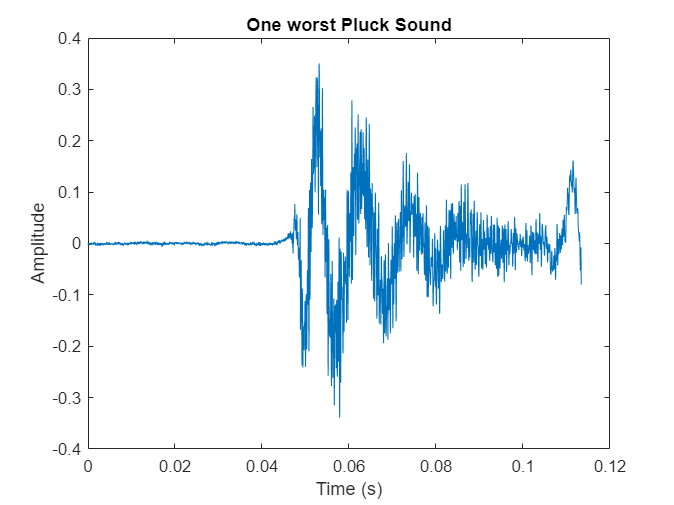

worst_pluck = y_worst(2000:7000);
t_worst = linspace(0,length(worst_pluck)/Fs,length(worst_pluck));
plot(t_worst, worst_pluck)
title("One worst Pluck Sound");
ylabel("Amplitude");
xlabel("Time (s)");

sound(worst_pluck, Fs)

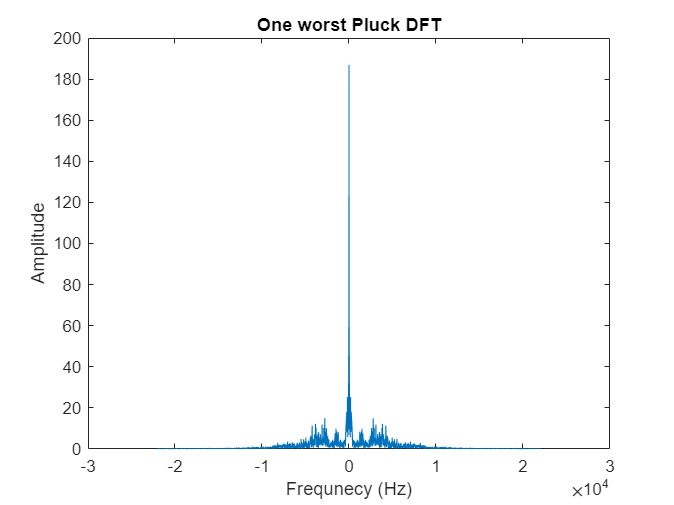

worst_N = length(worst_pluck);
worst_f = linspace(-Fs/2, Fs/2 - Fs/worst_N, worst_N) + Fs/(2*worst_N)*mod(worst_N, 2);

worst_pluckfft = fft(abs(worst_pluck));

worst_shiftpluckfft = fftshift(abs(worst_pluckfft));


plot(worst_f, worst_shiftpluckfft)
title("One worst Pluck DFT");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")

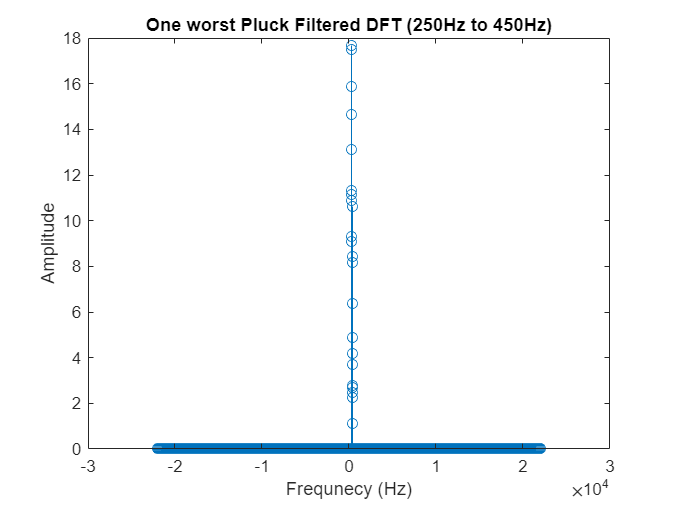


filter = zeros(length(worst_f), 1);
filter(worst_f >= 250 & worst_f <= 450) = 1;

filtered = worst_shiftpluckfft' .* filter;

stem(worst_f, filtered)
title("One worst Pluck Filtered DFT (250Hz to 450Hz)");
ylabel("Amplitude");
xlabel("Frequnecy (Hz)")